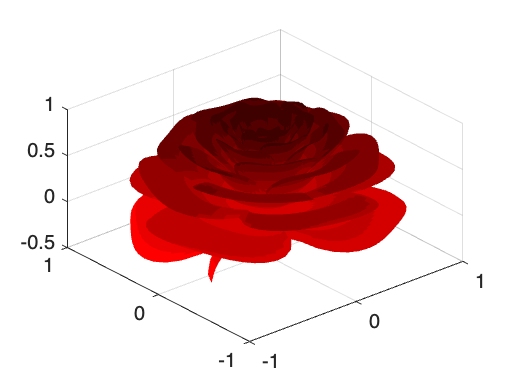

%% 
% Valentine day

n = 800;
A = 1.995653;
B = 1.27689;
C = 8;
r=linspace(0,1,n);
theta=linspace(-2,20*pi,n);
[R,THETA]=ndgrid(r,theta);
% define the number of petals we want per cycle. Roses have 3 and a bit.
petalNum=3.6;
x = 1 - (1/2)*((5/4)*(1 - mod(petalNum*THETA, 2*pi)/pi).^2 - 1/4).^2;
phi = (pi/2)*exp(-THETA/(C*pi));
y = A*(R.^2).*(B*R - 1).^2.*sin(phi);
R2 = x.*(R.*sin(phi) + y.*cos(phi));
X=R2.*sin(THETA);
Y=R2.*cos(THETA);
Z=x.*(R.*cos(phi)-y.*sin(phi));
% % define a red map for our rose colouring
red_map=linspace(1,0.25,10)';
red_map(:,2)=0;
red_map(:,3)=0;
clf
surf(X,Y,Z,'LineStyle','none')
view([-40.50 42.00])
colormap(red_map)

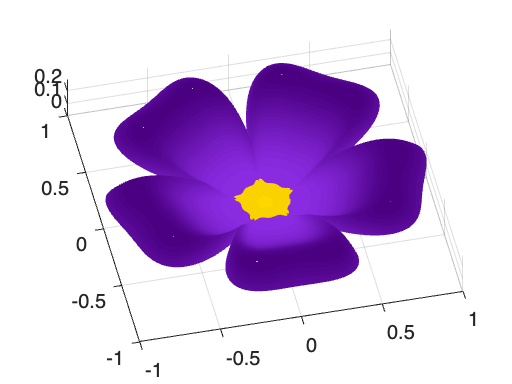

%%
n=800;
r=linspace(0,1,n);
theta=linspace(0,2*pi,n);
[R,THETA]=ndgrid(r,theta);
% define the number of petals we want per cycle. Violets have 5!
petalNum=5;
x = 1 - (1/2)*((5/4)*(1 - mod(petalNum*THETA, 2*pi)/pi).^2 - 1/4).^2;
% update the formula for phi to stop the spiralling effect
phi = (pi/2)*exp(-2*pi/(8*pi));
y = 1.95653*(R.^2).*(1.27689*R - 1).^2.*sin(phi);
R2 = x.*(R.*sin(phi) + y.*cos(phi));
X=R2.*sin(THETA);
Y=R2.*cos(THETA);
Z=x.*(R.*cos(phi)-y.*sin(phi));
% color code for blueviolet RGB 138,43,226
% Indigo rgb value (75,0,130)
mapSize=20;
blue_map=linspace(138,75,mapSize)';
blue_map(:,2)=linspace(43,0,mapSize)';
blue_map(:,3)=linspace(226,130,mapSize)';
% and a pretty bit in the middle
gold_map=[255 215 0; 250 210 0];
% combine to form a full flower map
violet_map=[gold_map; blue_map];
% Now lets plot it and try and pick an attractive angle
surf(X,Y,Z,'LineStyle','none')
colormap(violet_map/255)
view([-12.700 81.200])

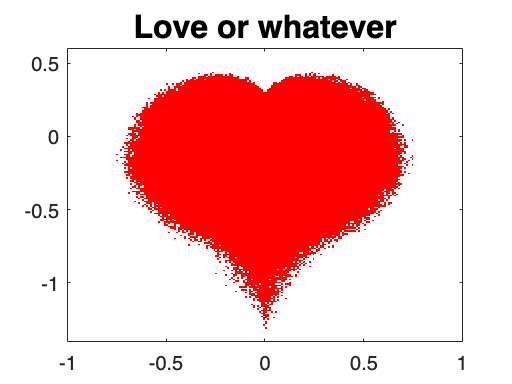


%% 
% % 
i = sqrt(-1);
% Fuzzy heart-shaped Mandelbrot fractal
% Mariano Beguerisse
% October 2010
% iterations
n = 300;
% resolution
N = 200;
% Create grid
x = linspace(-1, 1, N);
y = linspace(-1.4, .6, N);
[X,Y] = meshgrid(x, y);
Z = X + i*Y;
Zn = Z;
for j=1:n
 % Mandelbrot map with random noise
 Zn = -i*(Zn).^2 + (rand(N,N).^(1/5)).*Z;
 M = abs(Zn);
 ind1 = find(M<2);
 ind2 = find(M>=2);
 M(ind1) = 0;
 M(ind2) = -1;
end
imagesc(x, y, M)
colormap([1 1 1; 1 0 0])
set(gca, YDir="normal")
title("Love or whatever", FontSize=16)